# An example precision functional mapping routine

mkdir: 无法创建目录 “/home/poolab/HDD_4T/Stroke_data/TMS_Stroke/YangZhi/sub001/func/qa/GrayPlotQA/”: 没有那个文件或目录
已锁定最新绘图


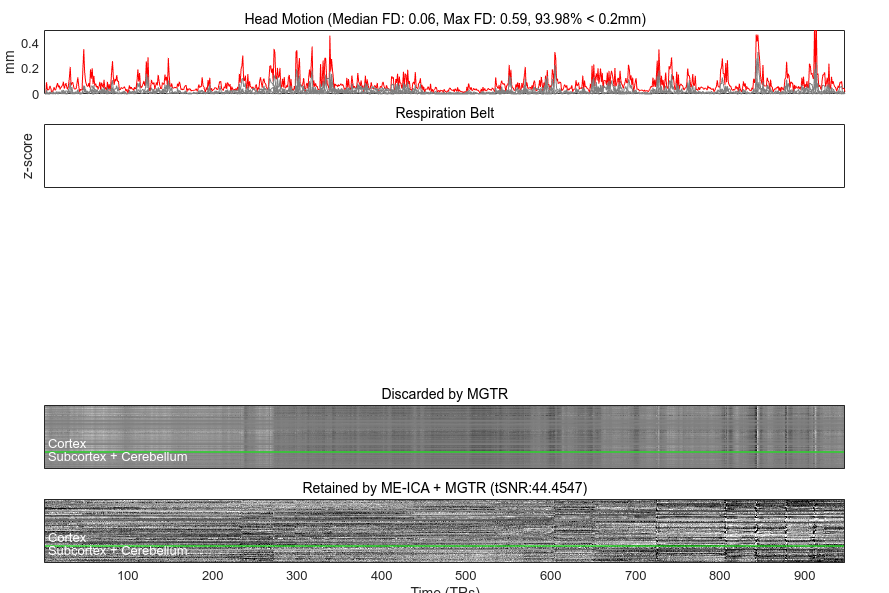

错误使用 saveas
路径无效或丢失:
/home/poolab/HDD_4T/Stroke_data/TMS_Stroke/YangZhi/sub001/func/qa/GrayPlotQA/GrayPlotQA_Session1_Run1.jpg

出错 grayplot_qa_func (第 163 行)
        saveas(gcf,[Subdir '/func/qa/GrayPlotQA/GrayPlotQA_Session' num2str(s) '_Run' num2str(r) '.jpg']); % save image

% define some paths
Paths{1} = '~/res0urces/'; % this folder contains ft_read / gifti functions for reading and writing cifti files (e.g., https://github.com/MidnightScanClub/MSCcodebase).
% Paths{2} = '/home/guoxl/fmridata/wyStroke/MSCcodebase-master'
% Paths{3} = '/home/guoxl/fmridata/wyStroke/MSCcodebase-master/Utilities/read_write_cifti/fileio'
% Paths{4} = '/home/guoxl/Documents/MATLAB/cifti-matlab-master'
% Paths{5} = '/home/guoxl/Documents/MATLAB/cifti-matlab-master/ft_cifti'
% Paths{6} = '/home/guoxl/Documents/MATLAB/cifti-matlab-master/ft_cifti/@gifti'


% define subject
% directory and surface files;
Subdir = '/home/poolab/HeJieShi/Patient_data/single_echo/ME20';
% Subdir = '/home/guoxl/fmridata/wyStroke/Liston-Laboratory-MultiEchofMRI-Pipeline-master/ExampleData_run2/ME16';
Subdir = '/home/poolab/HDD_4T/Stroke_data/TMS_Stroke/YangZhi/sub001';
str = strsplit(Subdir,'/'); Subject = str{end};
MidthickSurfs{1} = [Subdir '/anat/T1w/fsaverage_LR32k/' Subject '.L.midthickness.32k_fs_LR.surf.gii'];
MidthickSurfs{2} = [Subdir '/anat/T1w/fsaverage_LR32k/' Subject '.R.midthickness.32k_fs_LR.surf.gii'];

% denoising QC;
MeanFD = grayplot_qa_func(Subdir);

% grayplot_qa_func(Subdir);

## second run cancel


% concatenate and smooth resting-state fMRI datasets;
nSessions = length(dir([Subdir '/func/rest/session_*']));
[C,ScanIdx,FD] = concatenate_scans(Subdir,'Rest_OCME+MEICA+MGTR',1:nSessions);
mkdir([Subdir '/func/rest/ConcatenatedCiftis']);

cd([Subdir '/func/rest/ConcatenatedCiftis']);

% make distance matrix and then regress
% adjacent cortical signals from subcortical voxels;
make_distance_matrix(C,MidthickSurfs,[Subdir '/anat/T1w/fsaverage_LR32k/'],4);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

































[C] = regress_cortical_signals(C,[Subdir '/anat/T1w/fsaverage_LR32k/DistanceMatrix.mat'],20);
% hejieshi: regress llless subcortical signal
% [C] = regress_cortical_signals(C,[Subdir '/anat/T1w/fsaverage_LR32k/DistanceMatrix.mat'],10);
ft_write_cifti_mod([Subdir '/func/rest/ConcatenatedCiftis/Rest_OCME+MEICA+MGTR_Concatenated+SubcortRegression.dtseries.nii'],C);
save([Subdir '/func/rest/ConcatenatedCiftis/ScanIdx'],'ScanIdx');
save([Subdir '/func/rest/ConcatenatedCiftis/FD'],'FD');
clear C % clear intermediate file

% sweep a range of
% smoothing kernels;
for k = [0.85 1.7 2.55]
    smooth_cifti(Subdir,'Rest_OCME+MEICA+MGTR_Concatenated+SubcortRegression.dtseries.nii',['Rest_OCME+MEICA+MGTR_Concatenated+SubcortRegression+SpatialSmoothing' num2str(k) '.dtseries.nii'],k,k);
end


% load param




% load your concatenated resting-state dataset, here we selected the highest level of spatial smoothing
load([Subdir '/func/rest/ConcatenatedCiftis/FD']);
C = ft_read_cifti_mod([Subdir '/func/rest/ConcatenatedCiftis/Rest_OCME+MEICA+MGTR_Concatenated+SubcortRegression+SpatialSmoothing2.55.dtseries.nii']);
% C.data(:,FD>1.5)=[]; % remove high motion volumesFD
C.data(:,FD>0.3)=[]; % remove high motion volumes
C.data = single(C.data);


% pfm
% pfm(C,[Subdir '/anat/T1w/fsaverage_LR32k/DistanceMatrix.mat'],[Subdir '/pfm/'],[0.002],[50],20,[],{'CORTEX_LEFT','CEREBELLUM_LEFT','ACCUMBENS_LEFT','CAUDATE_LEFT','PALLIDUM_LEFT','PUTAMEN_LEFT','THALAMUS_LEFT','HIPPOCAMPUS_LEFT','AMYGDALA_LEFT','ACCUMBENS_LEFT','CORTEX_RIGHT','CEREBELLUM_RIGHT','ACCUMBENS_RIGHT','CAUDATE_RIGHT','PALLIDUM_RIGHT','PUTAMEN_RIGHT','THALAMUS_RIGHT','HIPPOCAMPUS_RIGHT','AMYGDALA_RIGHT','ACCUMBENS_RIGHT'},1);
% spatial_filtering([Subdir '/pfm/Bipartite_PhysicalCommunities.dtseries.nii'],[Subdir '/pfm/'],['Bipartite_PhysicalCommunities+SpatialFiltering.dtseries.nii'],MidthickSurfs,50,100);
setenv('LD_LIBRARY_PATH', sprintf('/home/poolab/anaconda3/lib:%s', getenv('LD_LIBRARY_PATH')));
pfm(C,[Subdir '/anat/T1w/fsaverage_LR32k/DistanceMatrix.mat'],[Subdir '/pfm/'],[0.0002 0.0005 0.001 0.002],[100 100 50 50],10,[],{'CORTEX_LEFT','CEREBELLUM_LEFT','ACCUMBENS_LEFT','CAUDATE_LEFT','PALLIDUM_LEFT','PUTAMEN_LEFT','THALAMUS_LEFT','HIPPOCAMPUS_LEFT','AMYGDALA_LEFT','ACCUMBENS_LEFT','CORTEX_RIGHT','CEREBELLUM_RIGHT','ACCUMBENS_RIGHT','CAUDATE_RIGHT','PALLIDUM_RIGHT','PUTAMEN_RIGHT','THALAMUS_RIGHT','HIPPOCAMPUS_RIGHT','AMYGDALA_RIGHT','ACCUMBENS_RIGHT'},1);

     1

Traceback (most recent call last):
  File "/home/poolab/anaconda3/bin/infomap", line 5, in <module>
    from infomap import main
  File "/home/poolab/anaconda3/lib/python3.9/site-packages/infomap.py", line 38, in <module>
    import _infomap
ImportError: /home/poolab/anaconda3/lib/python3.9/site-packages/_infomap.cpython-39-x86_64-linux-gnu.so: undefined symbol: _ZSt28__throw_bad_array_new_lengthv
     2

Traceback (most recent call last):
  File "/home/poolab/anaconda3/bin/infomap", line 5, in <module>
    from infomap import main
  File "/home/poolab/anaconda3/lib/python3.9/site-packages/infomap.py", line 38, in <module>
    import _infomap
ImportError: /home/poolab/anaconda3/lib/python3.9/site-packages/_infomap.cpython-39-x86_64-linux-gnu.so: undefined symbol: _ZSt28__throw_bad_array_new_lengthv
     3

Traceback (most recent call last):
  File "/home/poolab/anaconda3/bin/infomap", line 5, in <module>
    from infomap import main
  File "/home/poolab/anaconda3/lib/python3.9/

错误使用 readmatrix
找不到或无法打开
'/home/poolab/HDD_4T/Stroke_data/TMS_Stroke/YangZhi/sub001/pfm//Bipartite_Density0.0002.clu'。请
检查路径和文件名或文件权限。

出错 pfm (第 178 行)
    output = readmatrix([OutDir '/Bipartite_Density' num2str(Densities(d)) '.clu'],'Delimiter',' ','NumHeaderLines',9,'FileType','text');

spatial_filtering([Subdir '/pfm/Bipartite_PhysicalCommunities.dtseries.nii'],[Subdir '/pfm/'],['Bipartite_PhysicalCommunities+SpatialFiltering.dtseries.nii'],MidthickSurfs,100,100);


% pfm(C,[Subdir '/anat/T1w/fsaverage_LR32k/DistanceMatrix.mat'],[Subdir '/pfm/'],[0.0001 0.0002 0.0005 0.001 0.002 0.005 0.01],flip([50 100 100 200 200 200 400]),20,[],{'CORTEX_LEFT','CEREBELLUM_LEFT','ACCUMBENS_LEFT','CAUDATE_LEFT','PALLIDUM_LEFT','PUTAMEN_LEFT','THALAMUS_LEFT','HIPPOCAMPUS_LEFT','AMYGDALA_LEFT','ACCUMBENS_LEFT','CORTEX_RIGHT','CEREBELLUM_RIGHT','ACCUMBENS_RIGHT','CAUDATE_RIGHT','PALLIDUM_RIGHT','PUTAMEN_RIGHT','THALAMUS_RIGHT','HIPPOCAMPUS_RIGHT','AMYGDALA_RIGHT','ACCUMBENS_RIGHT'},1);
% spatial_filtering([Subdir '/pfm/Bipartite_PhysicalCommunities.dtseries.nii'],[Subdir '/pfm/'],['Bipartite_PhysicalCommunities+SpatialFiltering.dtseries.nii'],MidthickSurfs,200,200);


## pfm




pfm(C,[Subdir '/anat/T1w/fsaverage_LR32k/DistanceMatrix.mat'],[Subdir '/pfm/'],[0.0001 0.0002 0.0005 0.001 0.002 0.005],[],10,[],{'CORTEX_LEFT','CEREBELLUM_LEFT','ACCUMBENS_LEFT','CAUDATE_LEFT','PALLIDUM_LEFT','PUTAMEN_LEFT','THALAMUS_LEFT','HIPPOCAMPUS_LEFT','AMYGDALA_LEFT','ACCUMBENS_LEFT','CORTEX_RIGHT','CEREBELLUM_RIGHT','ACCUMBENS_RIGHT','CAUDATE_RIGHT','PALLIDUM_RIGHT','PUTAMEN_RIGHT','THALAMUS_RIGHT','HIPPOCAMPUS_RIGHT','AMYGDALA_RIGHT','ACCUMBENS_RIGHT'},1);
spatial_filtering([Subdir '/pfm/Bipartite_PhysicalCommunities.dtseries.nii'],[Subdir '/pfm/'],['Bipartite_PhysicalCommunities+SpatialFiltering.dtseries.nii'],MidthickSurfs,100,100);


system(['cp ' Subdir '/pfm/Bipartite_PhysicalCommunities+SpatialFiltering.dtseries.nii ' Subdir '/pfm/' Subject '_FunctionalNetworks.dtseries.nii'])
% 
% 
% pfm(C,[Subdir '/anat/T1w/fsaverage_LR32k/DistanceMatrix.mat'],[Subdir '/pfm/'],[0.0001 0.0002 0.0005 0.001 0.002 0.005],flip([]),10,[],{'CORTEX_LEFT','CEREBELLUM_LEFT','ACCUMBENS_LEFT','CAUDATE_LEFT','PALLIDUM_LEFT','PUTAMEN_LEFT','THALAMUS_LEFT','HIPPOCAMPUS_LEFT','AMYGDALA_LEFT','ACCUMBENS_LEFT','CORTEX_RIGHT','CEREBELLUM_RIGHT','ACCUMBENS_RIGHT','CAUDATE_RIGHT','PALLIDUM_RIGHT','PUTAMEN_RIGHT','THALAMUS_RIGHT','HIPPOCAMPUS_RIGHT','AMYGDALA_RIGHT','ACCUMBENS_RIGHT'},1);
% spatial_filtering([Subdir '/pfm/Bipartite_PhysicalCommunities.dtseries.nii'],[Subdir '/pfm/'],['Bipartite_PhysicalCommunities+SpatialFiltering.dtseries.nii'],MidthickSurfs,200,200);


## Run pfm


% run precision mapping; (Note: there are hard set paths related to the resources folder and infomap in "pfm.m" user must first set)
pfm(C,[Subdir '/anat/T1w/fsaverage_LR32k/DistanceMatrix.mat'],[Subdir '/pfm/'],[0.005],[50],10,[],{'CORTEX_LEFT','CORTEX_RIGHT','CEREBELLUM_LEFT','ACCUMBENS_LEFT','CAUDATE_LEFT','PALLIDUM_LEFT','PUTAMEN_LEFT','THALAMUS_LEFT','HIPPOCAMPUS_LEFT','AMYGDALA_LEFT','ACCUMBENS_LEFT','CORTEX_RIGHT','CEREBELLUM_RIGHT','ACCUMBENS_RIGHT','CAUDATE_RIGHT','PALLIDUM_RIGHT','PUTAMEN_RIGHT','THALAMUS_RIGHT','HIPPOCAMPUS_RIGHT','AMYGDALA_RIGHT','ACCUMBENS_RIGHT'},1);

## Filtering


% pfm(C,[Subdir '/anat/T1w/fsaverage_LR32k/DistanceMatrix.mat'],[Subdir '/pfm/'],flip([0.0001 0.0002 0.0005 0.001 0.002 0.005 0.01 0.02 0.05]),[1 5 10 50 50 50 50 50 50],10,[],{'CORTEX_LEFT','CEREBELLUM_LEFT','ACCUMBENS_LEFT','CAUDATE_LEFT','PALLIDUM_LEFT','PUTAMEN_LEFT','THALAMUS_LEFT','HIPPOCAMPUS_LEFT','AMYGDALA_LEFT','ACCUMBENS_LEFT','CORTEX_RIGHT','CEREBELLUM_RIGHT','ACCUMBENS_RIGHT','CAUDATE_RIGHT','PALLIDUM_RIGHT','PUTAMEN_RIGHT','THALAMUS_RIGHT','HIPPOCAMPUS_RIGHT','AMYGDALA_RIGHT','ACCUMBENS_RIGHT'},1);

pfm(C,[Subdir '/anat/T1w/fsaverage_LR32k/DistanceMatrix.mat'],[Subdir '/pfm/'],[0.0001 0.0002 0.005 0.01 0.02 0.03],flip([10 10 10 50 50 50]),10,[],{'CORTEX_LEFT','CEREBELLUM_LEFT','ACCUMBENS_LEFT','CAUDATE_LEFT','PALLIDUM_LEFT','PUTAMEN_LEFT','THALAMUS_LEFT','HIPPOCAMPUS_LEFT','AMYGDALA_LEFT','ACCUMBENS_LEFT','CORTEX_RIGHT','CEREBELLUM_RIGHT','ACCUMBENS_RIGHT','CAUDATE_RIGHT','PALLIDUM_RIGHT','PUTAMEN_RIGHT','THALAMUS_RIGHT','HIPPOCAMPUS_RIGHT','AMYGDALA_RIGHT','ACCUMBENS_RIGHT'},1);




spatial_filtering([Subdir '/pfm/Bipartite_PhysicalCommunities.dtseries.nii'],[Subdir '/pfm/'],['Bipartite_PhysicalCommunities+SpatialFiltering.dtseries.nii'],MidthickSurfs,400,400);

% remove some intermediate files;
% system(['rm ' Subdir '/pfm/*.net']);
% system(['rm ' Subdir '/pfm/*.clu']);
% system(['rm ' Subdir '/pfm/*Log*']);

## tmp

Subdir = '/home/guoxl/fmridata/wyStroke/Liston-Laboratory-MultiEchofMRI-Pipeline-master/example_data_from_github/ME01';
str = strsplit(Subdir,'/'); Subject = str{end};
MidthickSurfs{1} = [Subdir '/anat/T1w/fsaverage_LR32k/' Subject '.L.midthickness.32k_fs_LR.surf.gii'];
MidthickSurfs{2} = [Subdir '/anat/T1w/fsaverage_LR32k/' Subject '.R.midthickness.32k_fs_LR.surf.gii'];

spatial_filtering([Subdir '/pfm/Bipartite_PhysicalCommunities.dtseries.nii'],[Subdir '/pfm/'],['Bipartite_PhysicalCommunities+SpatialFiltering.dtseries.nii'],MidthickSurfs,400,400);
